clc
clear
A = [5  8  12];
B = [106.8 177.2 279.2];
syms x V(x);
V(x)=lagrange(A,B);
V3 = vpa(V(10))

$$V3 = 227.0380952380952380952380952381$$

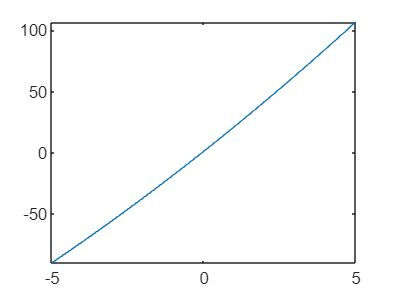

fplot(V(x));

function [out] = lagrange(A,B)
n = length(A);
syms x V(x);
V(x) = 0;
for i = 1 : n
    L = 1;
    for j = 1 : n
        if j~=i
            L = L*(x-A(j))/(A(i)-A(j));
        end
    end
    V(x) = V(x) + L*B(i);
out = V(x);
end
end